# lab1 - Pietro Alovisi

## Setup

% add path containing lab files
addpath('../LabFiles/Functions/');

## Fourier transform

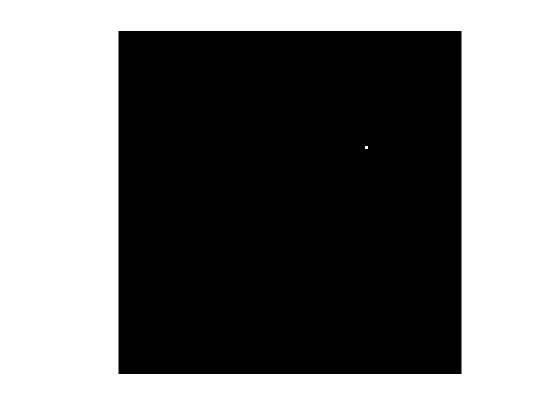

Fhat = zeros(128, 128);

p = 44; 
q = 93;
Fhat(p , q ) = 1;
figure(1);
showgrey(Fhat);

now let's compute the fourier transform

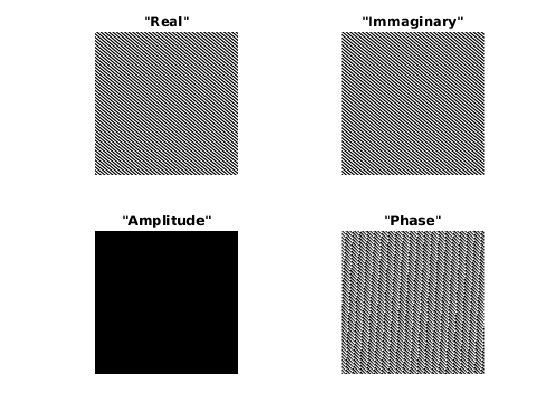


F = ifft2(Fhat);
Fabsmax = max(abs(F(:)));
figure(2);
subplot(2,2,1);
showgrey(real(F), 64, -Fabsmax, Fabsmax)
title "Real";

subplot(2,2,2);
showgrey(imag(F), 64, -Fabsmax, Fabsmax)
title "Immaginary";

subplot(2,2,3);
showgrey(log(abs(F)), 64, -Fabsmax, Fabsmax)
title "Amplitude";

subplot(2,2,4);
showgrey(angle(F), 64, -pi, pi)
title "Phase";

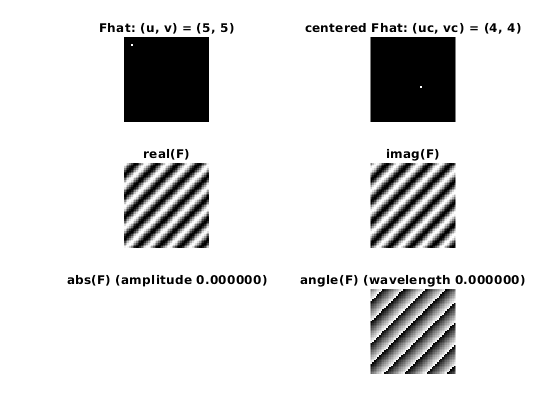



figure(3)
fftwave(5,5,50);